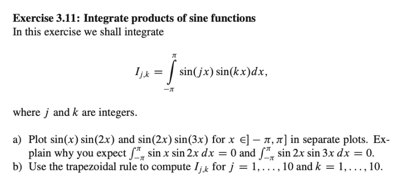

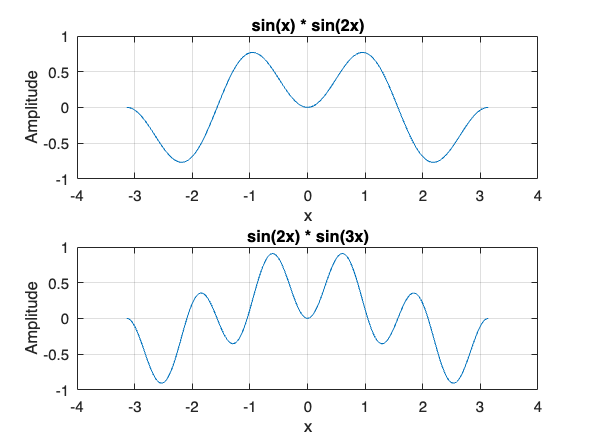

%plots
%define interval
x = linspace(-pi, pi, 1000);

%define functions
y1 = sin(x) .* sin(2*x);
y2 = sin(2*x) .* sin(3*x);

figure;
subplot(2, 1, 1);
plot(x, y1);
title('sin(x) * sin(2x)');
xlabel('x');
ylabel('Amplitude');
grid on;

subplot(2, 1, 2);
plot(x, y2);
title('sin(2x) * sin(3x)');
xlabel('x');
ylabel('Amplitude');
grid on;


%integration
N = 1000;  %number of trapezoids
a = -pi;
b = pi;

%compute the integral
compute_integral = @(j, k) trapezoidal_vec(@(x) sin(j * x) .* sin(k * x), a, b, N);

%use arrayfun to apply the integral function above to all combinations of j and k
[j_vals, k_vals] = meshgrid(1:10, 1:10);
I = arrayfun(compute_integral, j_vals, k_vals);

%display the result
disp(I);

    3.1416   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000
   -0.0000    3.1416    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    3.1416    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.0000    0.0000    0.0000    3.1416   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.0000   -0.0000    0.0000   -0.0000    3.1416   -0.0000   -0.0000    0.0000    0.0000   -0.0000
   -0.0000   -0.0000    0.0000    0.0000   -0.0000    3.1416   -0.0000   -0.0000   -0.0000    0.0000
    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    3.1416    0.0000    0.0000    0.0000
    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    3.1416    0.0000   -0.0000
    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    3.1416   -0.0000
   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000 